# **Introductory script illustrating how to compute cone mosaic photocurrent responses in the presence of fixational eye movements.**

***This tutorial generates an ISETBio scene representing a Gabor stimulus as realized on a particular display, passes this scene through the default wavefront-aberration based human optics, and computes cone mosaic excitation and photocurrent responses in the presence of fixational eye movements. ***

#### **See also**: 

- `t_sceneForStimulusOnDisplay.mlx`  (more info on scene generation)

- t_conePhotocurrentsFromSceneOnDisplay.mlx (photocurrent computation + fixational eye movements)

- `t_treeShrewConeIsomerizationsFromSceneOnDisplay.mlx ` (parameters specific to treeshrew visual system)

*Copyright: Nicolas P. Cottaris,  ISETBio Team,, 2018*

# OUTLINE

 **   Step 1.** Create a presentation display and a Gabor stimulus realized on that display

 **   Step 2.** Compute the optical image using wavefront-aberration based optics

   ** Step 3.** Create a cone mosaic object and fixational eye movements

   ** Step 4.** Compute the mosaic's isomerization and photocurrent response 

# **Step 1.** Create a presentation display and a low-frequency Gabor stimulus realized on that display

We employ an existing display specification, here an Apple LCD display and some typical params for a Gabor stimulus.

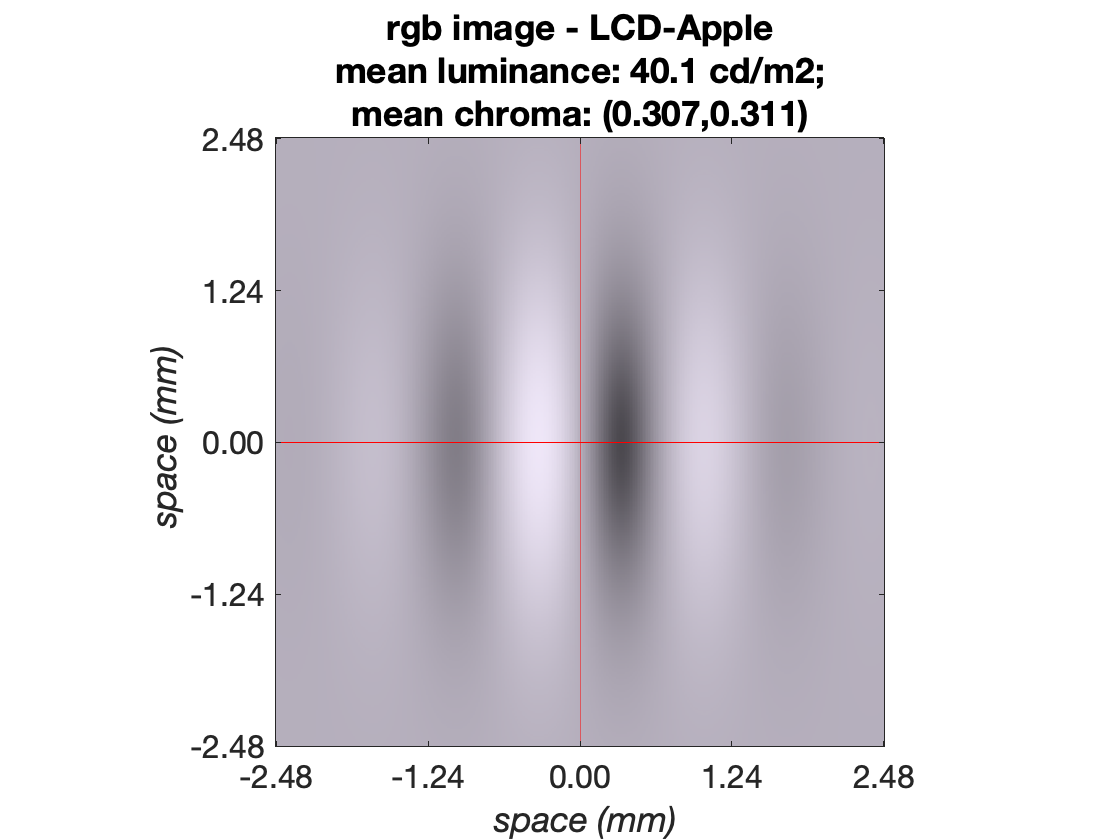

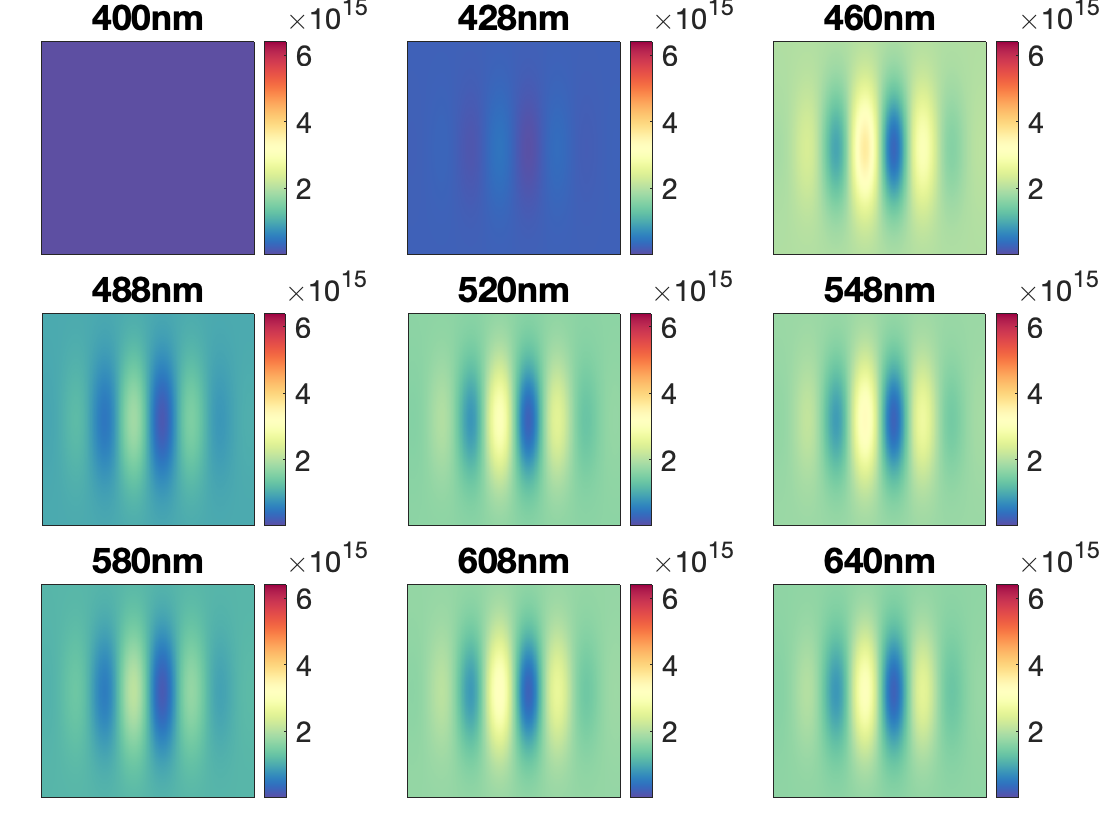

%% Create presentation display and place it 57 cm in front of the eye
presentationDisplay = displayCreate('LCD-Apple', 'viewing distance', 0.57);


%% parameter struct for a Gabor stimulus 
stimParams = struct(...
    'spatialFrequencyCyclesPerDeg', 7, ...  % 7 cycles/deg
    'orientationDegs', 0, ...               % 0 degrees
    'phaseDegs', 90, ...                    % spatial phase in degrees
    'sizeDegs', 0.5, ...                    % 0.5 x 0.5 degrees
    'sigmaDegs', 0.3/3, ...                 % sigma of Gaussian envelope, in degrees
    'contrast', 0.9,...                     % 0.9 Michelson contrast
    'meanLuminanceCdPerM2', 40, ...         % 40 cd/m2 mean luminance
    'pixelsAlongWidthDim', [], ...          % pixels- width dimension
    'pixelsAlongHeightDim', [] ...          % pixel- height dimension
    );

% Generate a scene representing the Gabor stimulus with the above params as
% realized on the presentationDisplay
realizedStimulusScene = generateGaborScene(...
    'stimParams', stimParams,...
    'presentationDisplay', presentationDisplay);

% Visualize different aspects of the generated scene
visualizeScene(realizedStimulusScene);

# **Step 2.** Compute the optical image using wavefront-aberration based optics

We employ the default human optics model which is based on average Zernike coefficiencts from 200 human subjects. The scene is passed through the optics model to compute the retinal image.

### Step 2.1 Generate the default human optics model 

%% Generate wavefront-aberration derived human optics
theOI = oiCreate('wvf human');

### Step 2.2 Generate the retinal optical image by passing the scene though the optics

Compute the retinal image.

%% Compute the retinal image
theOI = oiCompute(theOI, realizedStimulusScene);

Note that the chromaticity of the optical image is different from that of the scene - it is more yellowish. This is due to absorption of short wavelength light by the lens. 

# **Step 3.** Create a cone mosaic object and fixational eye movements

### Step 3.1 Generate the cone mosaic

We generate a hexagonal, eccentricity-varying cone mosaic, with an integration time of 20 mseconds, and then compute its excitation response to the retinal image generated previously.

%% Generate a hexagonal cone mosaic with ecc-based cone quantal efficiency
theMosaic = coneMosaicHex(5, ...              % hex lattice sampling factor
   'fovDegs', stimParams.sizeDegs, ...        % match mosaic width to stimulus size
   'eccBasedConeDensity', true, ...           % cone density varies with eccentricity
   'eccBasedConeQuantalEfficiency', true, ... % cone quantal efficiency varies with eccentricity
   'integrationTime', 5/1000, ...             % 5 msec integration time
   'maxGridAdjustmentIterations', 50);        % terminate iterative lattice adjustment after 50 iterations


Hex grid adjustment: on iteration 0 ... 
Hex grid adjustment: on iteration 1 ... 
Hex grid adjustment: on iteration 2 ... 
Hex grid adjustment: on iteration 3 ... 
Hex grid adjustment: on iteration 4 ... 
Hex grid adjustment: on iteration 5 ... 
Hex grid adjustment: on iteration 6 ... 
Hex grid adjustment: on iteration 7 ... 
Hex grid adjustment: on iteration 8 ... 
Hex grid adjustment: on iteration 9 ... 
Hex grid adjustment: on iteration 10 ... 
Hex grid adjustment: on iteration 11 ... 
Hex grid adjustment: on iteration 12 ... 
Hex grid adjustment: on iteration 13 ... 
Hex grid adjustment: on iteration 14 ... 
Hex grid adjustment: on iteration 15 ... 
Hex grid adjustment: on iteration 16 ... 
Hex grid adjustment: on iteration 17 ... 
Hex grid adjustment: on iteration 18 ... 
Hex grid adjustment: on iteration 19 ... 
Hex grid adjustment: on iteration 20 ... 
Hex grid adjustment: on iteration 21 ... 
Hex grid adjustment: on iteration 22 ... 
Hex grid adjustment: on iteration 23 ... 
H

### Step 3.2 Generate fixational eye movements

Here we call the **emGenSequence() **method of coneMosaic to generate fixational eye movement paths. 

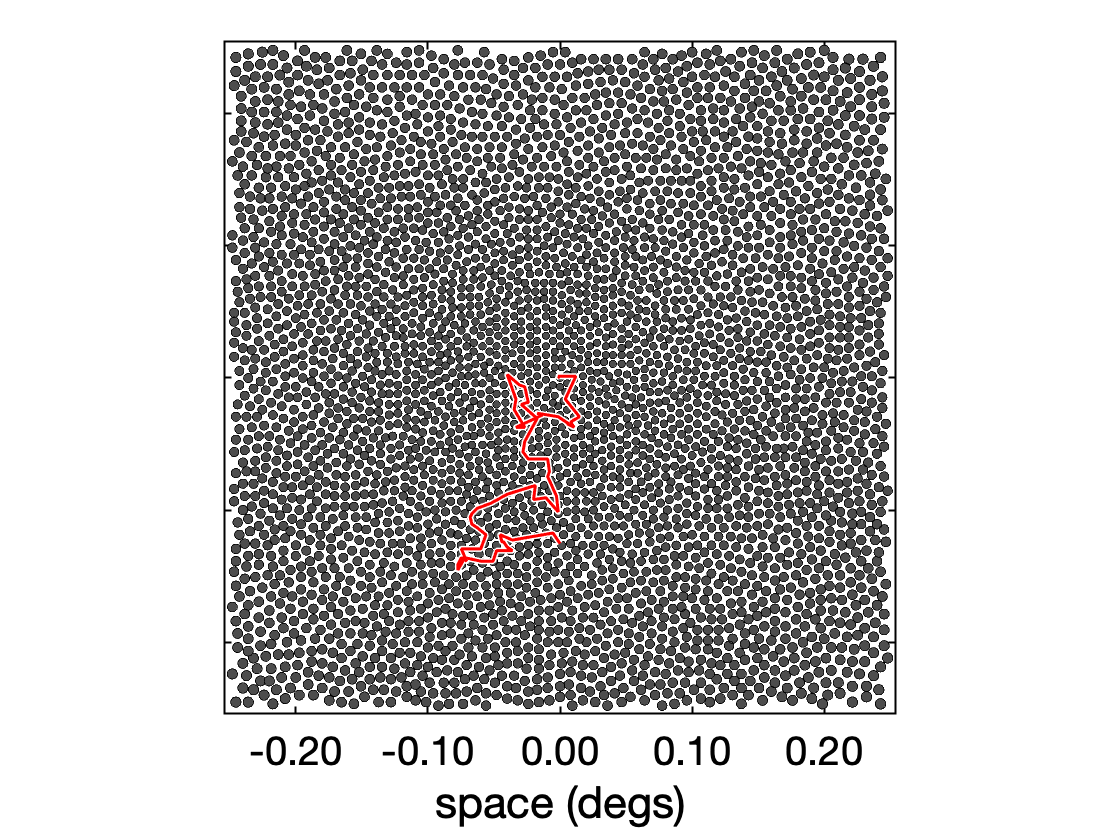

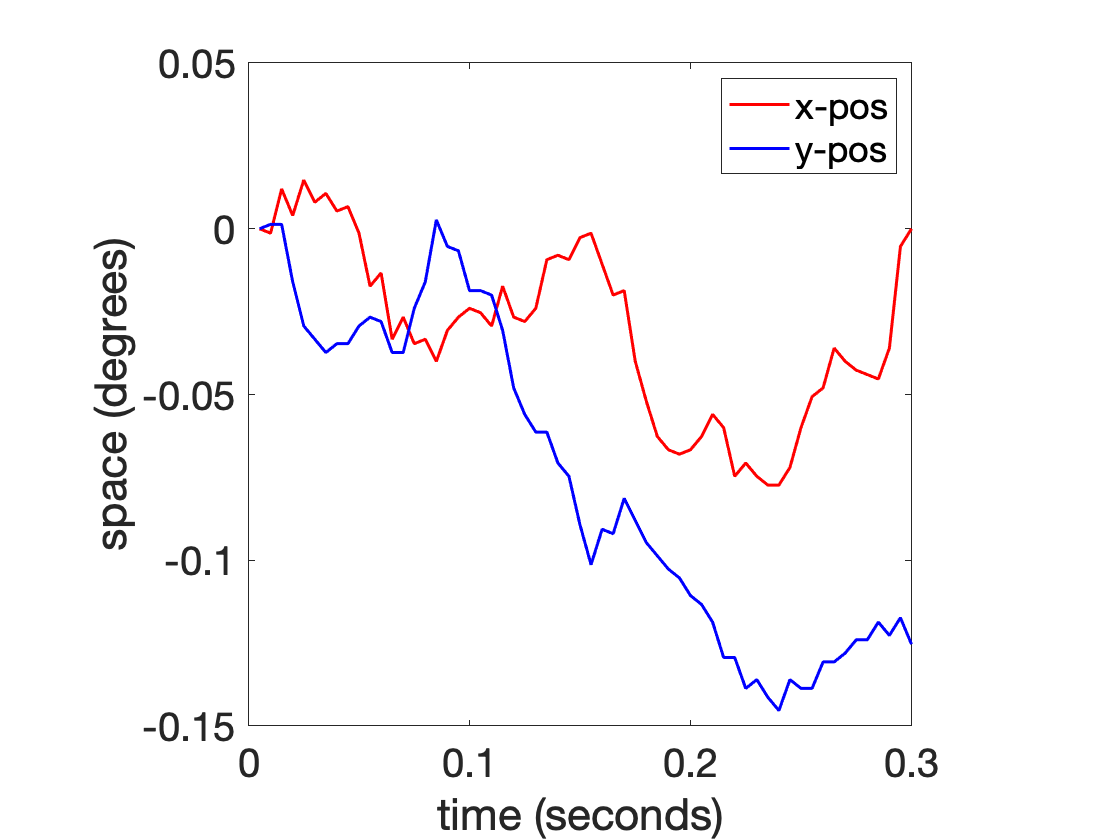

% Generate two instances of fixational eye eyemovements 
% each with 60 position samples. Given an integrationTime of 5 msec,
% this corresponds to a 60*5 = 300 msec long fixation
eyeMovementsNum = 60;
[emPaths, fixEMOBJ] = theMosaic.emGenSequence(eyeMovementsNum, 'nTrials', 2);

% Plot the first eye movement trajectory
visualizeConeMosaicAndEMPath(theMosaic, fixEMOBJ);

# **Step 4.** Compute the mosaic's isomerization response and photocurrent response.

### Step 4.1 Compute excitation and photocurrent responses

Here we compute cone excitation and photocurrent responses in the presence of fixational eye movements. We actually use the same fixational eye movement path repeated N trials in order to better visualize the signal/noise ratio of the excitation and the photocurrent responses.

% Make nTrialsNum replicas of a single eye movement path
nTrialsNum = 16;
repeatedEMPath = 0*repmat(emPaths(1,:,:), [nTrialsNum 1 1]);

% Compute mosaic responses to the repeated emPath
[coneExcitations, photoCurrents] = theMosaic.compute(theOI, ...
     'emPath', repeatedEMPath, 'currentFlag', true);

### Step 4.2 Visualize results. 

We are visualizing the cone mosaic on the left, along with the first two response instances. All computed responses instances for cones located along the horizontal meridian are visualized on the bottom plot.

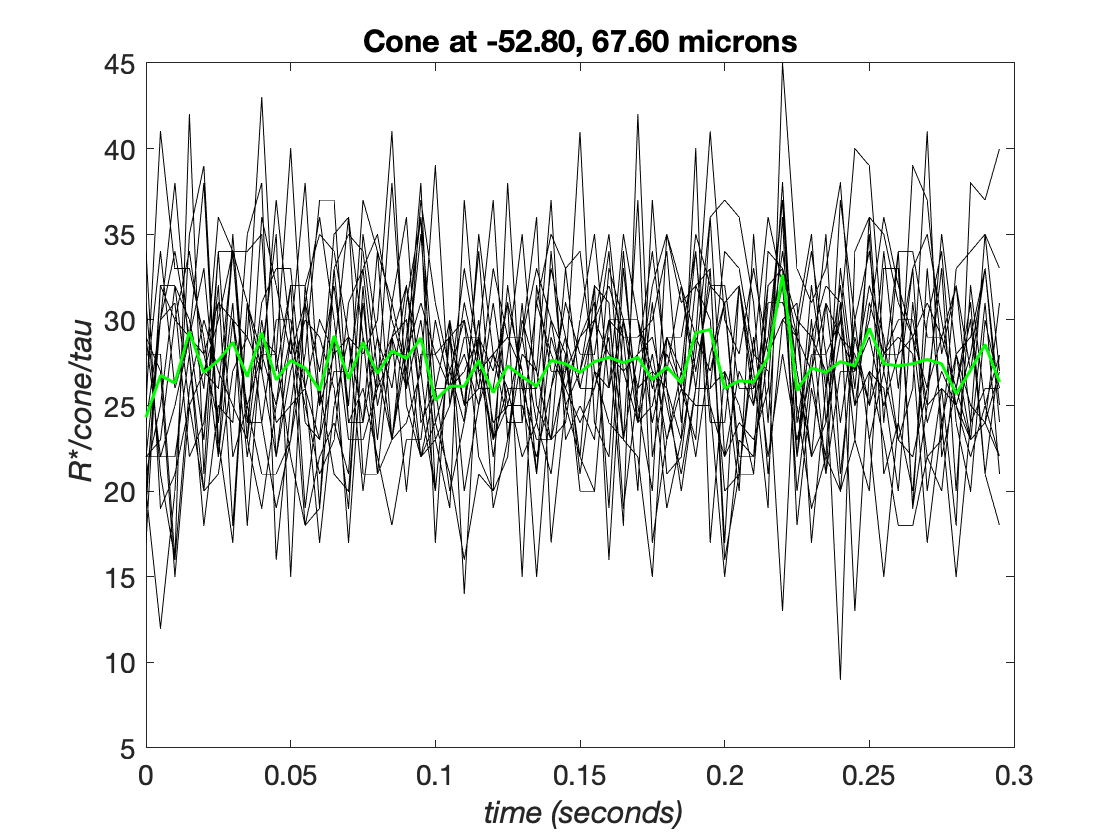

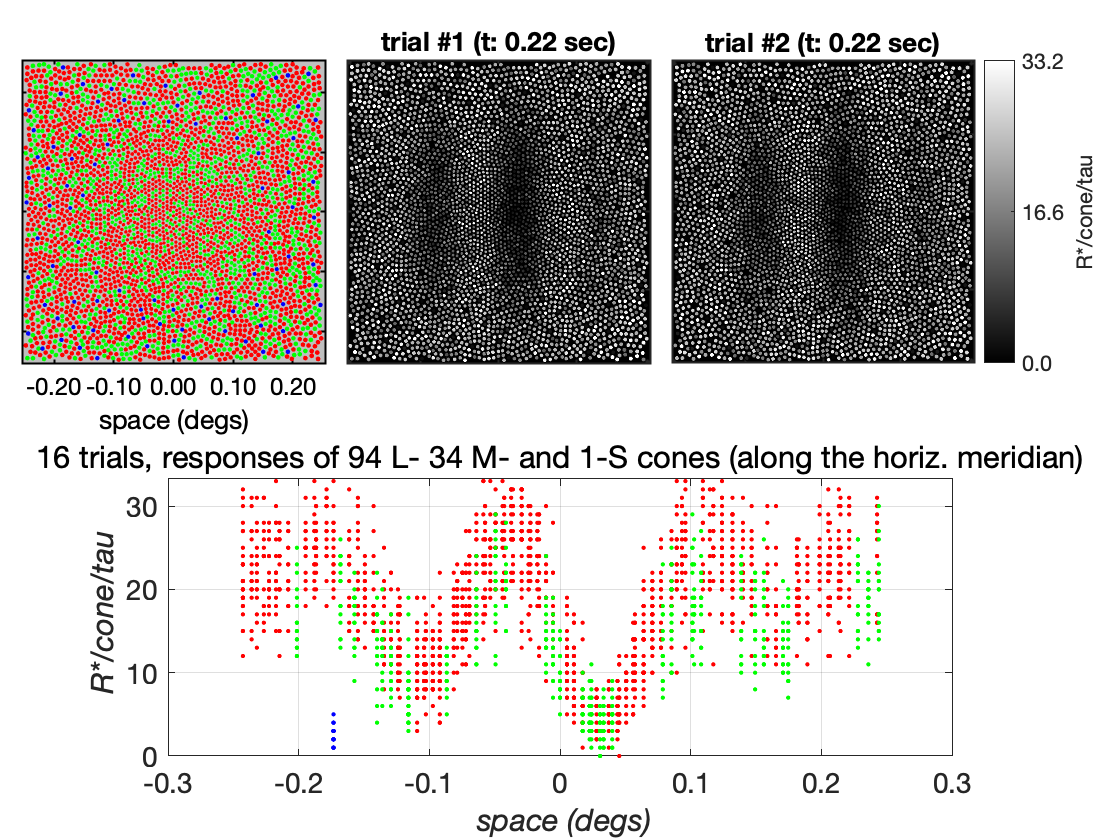

%% Visualize cone mosaic and its cone excitation responses
visualizeConeMosaicResponses(theMosaic, coneExcitations, 'R*/cone/tau');

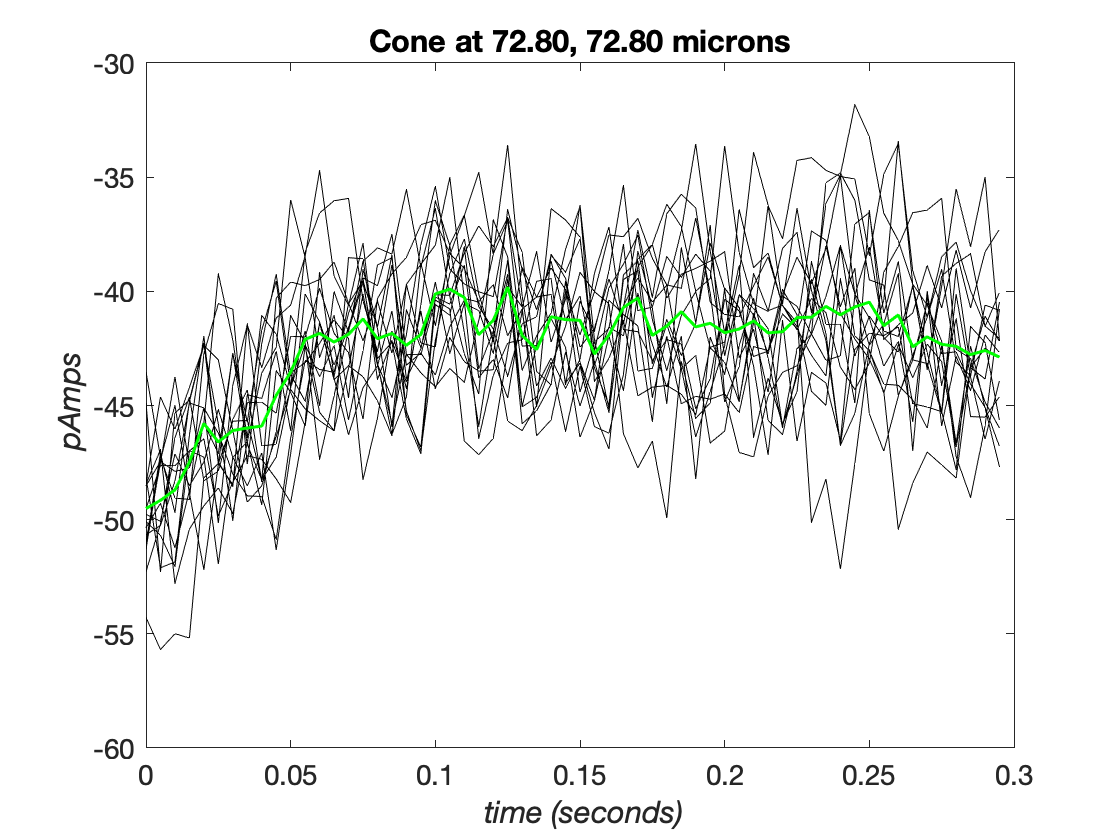

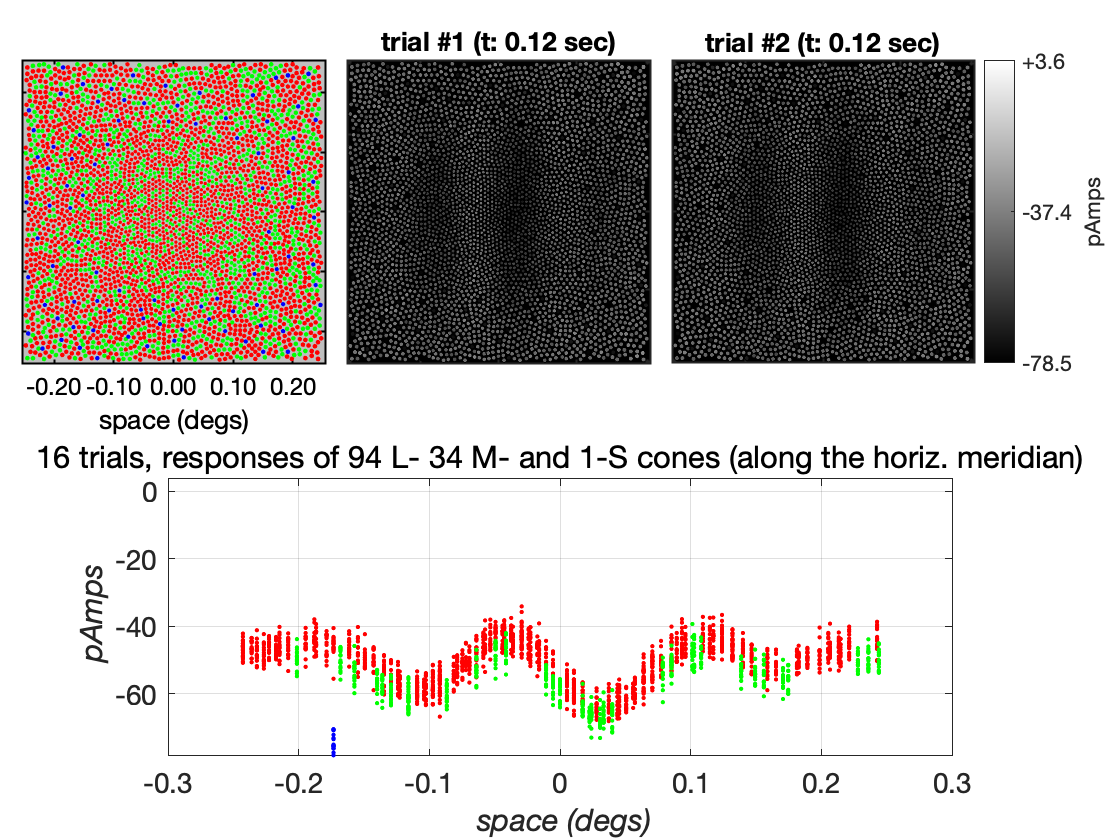


%% Visualize cone mosaic and its photocurrent responses
visualizeConeMosaicResponses(theMosaic, photoCurrents, 'pAmps');